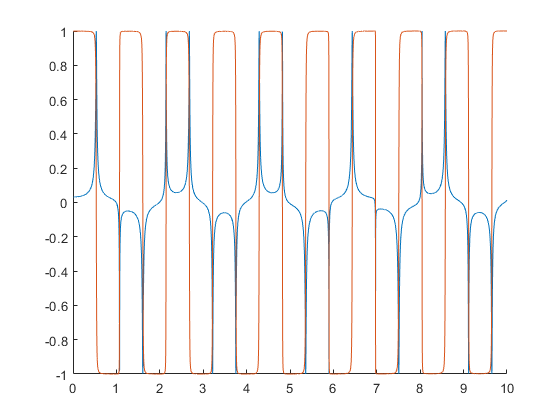

%计算旋转轴与坐标轴的夹角
B0 = 401;%magnetic field
gama0 = 10.7083e-4;%C13 parameter
tmax = 10;
tstep = 0.001;
t = (0.01:tstep:tmax)';
%set parameter...
% wh0 = 1e-3*[83.8,47,55,19,33,25.1];
% th0 = pi/180*[21,30,54,133,132,51];
% wh = 1e-3*[45];
% th = pi/180*[32];
N = 56; 
% A = wh.*cos(th);
% B = wh.*sin(th);
A = 72.8e-3;
B = 30e-3;
wl = 2*pi*gama0*B0;
S = Kernal2(A,B,wl,N,t);
wb = S.get_wb();
mx = S.get_mx();
mz = S.get_mz();
beta = t*wl;
alpha = t*wb;
phi = acos(cos(alpha).*cos(beta)-mz(1)*sin(alpha).*sin(beta));
n0x = mx*sin(alpha)./(sin(phi));
n0z = (mz(1)*cos(beta).*sin(alpha)+cos(alpha).*sin(beta))./(sin(phi));
N_t = pi./phi;
figure
hold on;
plot(t,n0x);
plot(t,n0z);

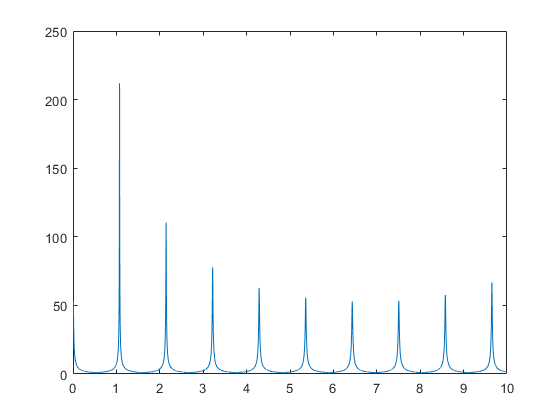

figure
plot(t,N_t);